out=sim('testing')

out =   Simulink.SimulationOutput:

                      e: [1x1 timeseries] 
                   tout: [501x1 double] 
                      u: [1x1 timeseries] 
                      y: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


Simulation

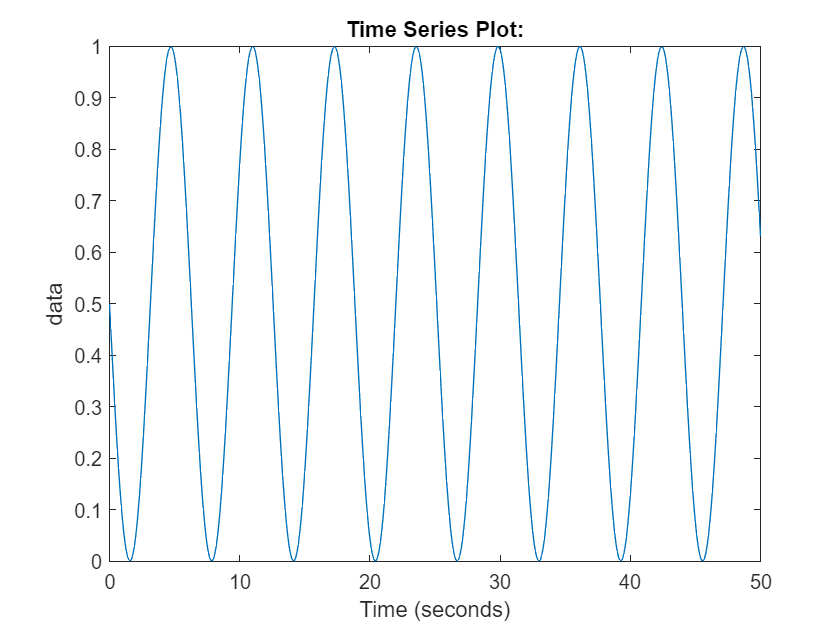

plot(out.u)

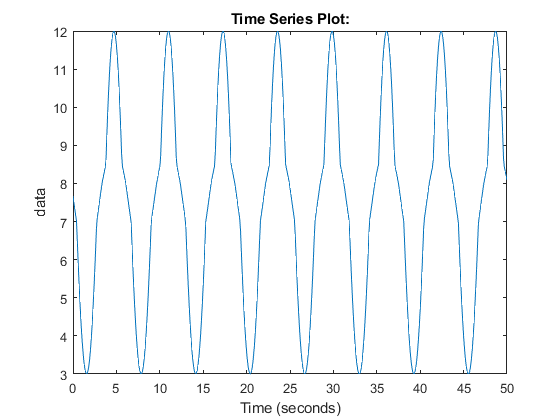

plot(out.y)

out2=sim('testing2.slx')

out2 =   Simulink.SimulationOutput:

                     e1: [1x1 timeseries] 
                   tout: [501x1 double] 
                     u1: [1x1 timeseries] 
                     y1: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


for 5 mf trimf

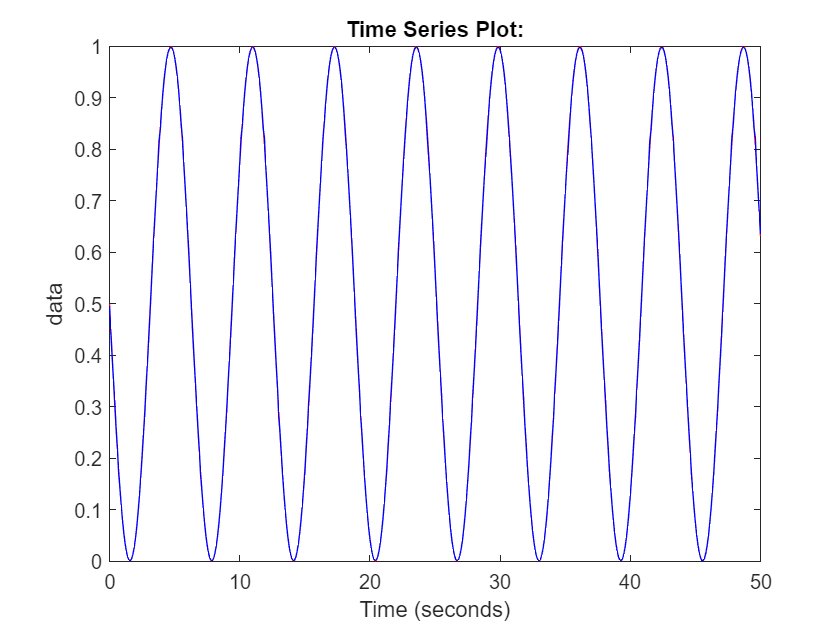

plot(out2.u1,'r');hold on;
plot(out2.y1,'b');hold off;

out3=sim('testing3')

out3 =   Simulink.SimulationOutput:

                     e1: [1x1 timeseries] 
                   tout: [501x1 double] 
                     u1: [1x1 timeseries] 
                     y1: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


for 5 mf gauss2mf

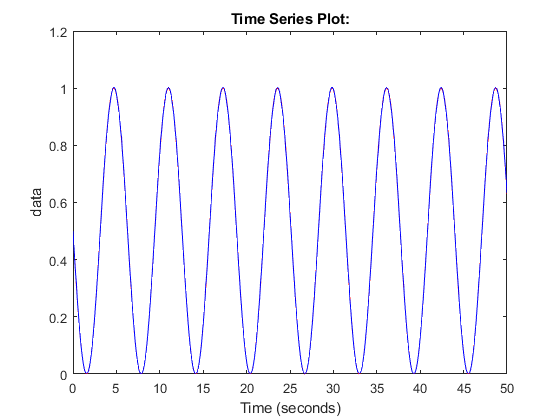

plot(out3.u1,'r');hold on
plot(out3.y1,'b');hold off

for 2 mf trimf

out4=sim("testing4.slx")

out4 =   Simulink.SimulationOutput:

                     e1: [1x1 timeseries] 
                   tout: [501x1 double] 
                     u1: [1x1 timeseries] 
                     y1: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


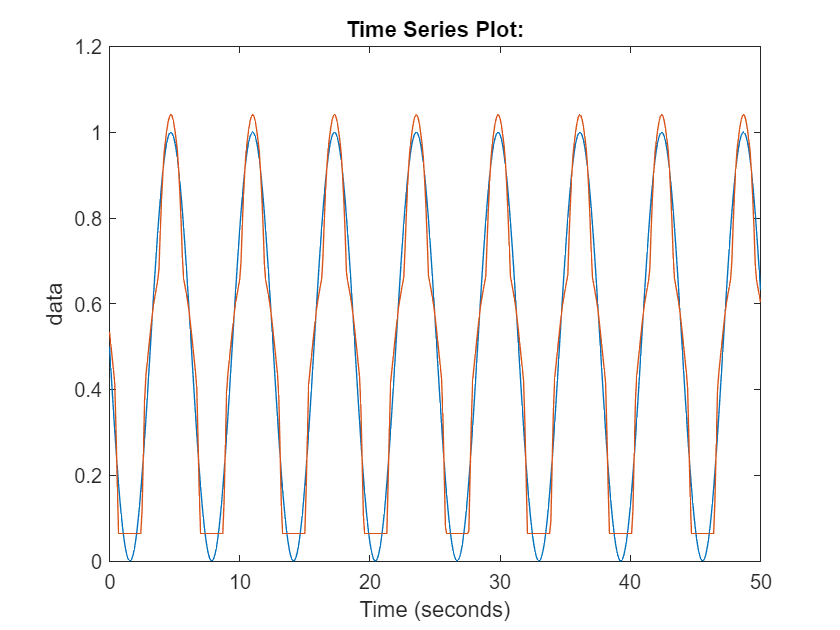

plot(out4.u1);hold on
plot(out4.y1);hold off

for 2 mf gauss2mf

out5=sim("testing5.slx")

out5 =   Simulink.SimulationOutput:

                     e1: [1x1 timeseries] 
                   tout: [501x1 double] 
                     u1: [1x1 timeseries] 
                     y1: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


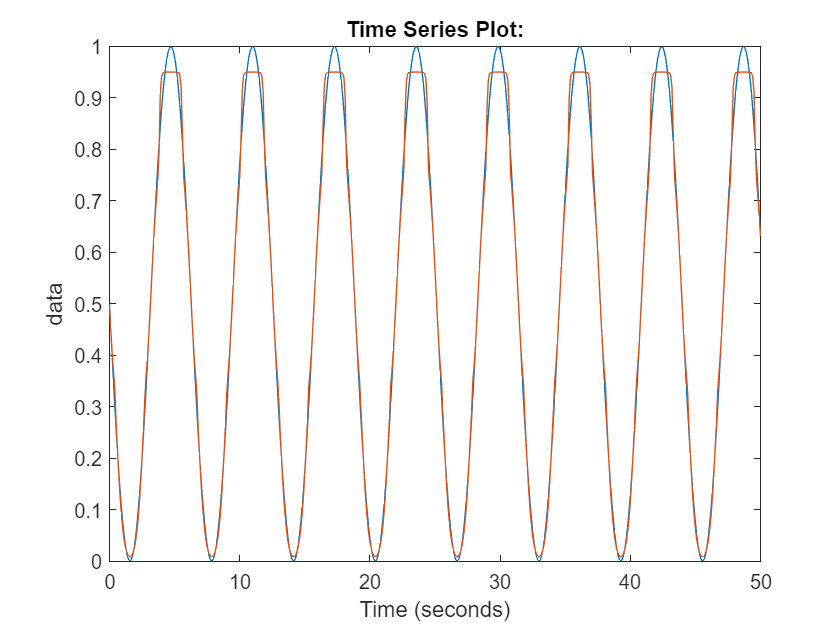

plot(out5.u1);hold on
plot(out5.y1);hold off

ERROR of each FIS system

For 2 mf trimf:

error=erfunc(out4.u1.DATA,out4.y1.DATA)

error = 1.8731

Mean_absolute_error=mae(out4.u1.DATA,out4.y1.DATA)

Mean_absolute_error = 0.0514

For 5 mf trimf

error1=erfunc(out2.u1.DATA,out2.y1.DATA)

error1 = 0.0044

Mean_absolute_error1=mae(out2.u1.DATA,out2.y1.DATA)

Mean_absolute_error1 = 0.0020

For 2 mf gauss2mf

error2=erfunc(out5.u1.DATA,out5.y1.DATA)

error2 = 0.3099

Mean_absolute_error2=mae(out5.u1.DATA,out5.y1.DATA)

Mean_absolute_error2 = 0.0175

5 mf gauss2mf

error3=erfunc(out3.u1.DATA,out3.y1.DATA)

error3 = 0.0045

Mean_absolute_error3=mae(out3.u1.DATA,out3.y1.DATA)

Mean_absolute_error3 = 0.0023

Sum of squared difference of each array entry e=(x-y)^2

function error=erfunc(x,y)
error=ones(1,length(x))*(x-y).^2;
end
